# This script generates Figure 11

The figure reproduces a data contamination scheme used in the paper to test the performances of Algorithm 3. The good data comes from a $t$-distribution. The contaminating component of $n\varepsilon$ observations is generated from a uniform distribution over a $p$-dimensional hyper-rectangle of mean $10 \cdot \mathbf{1}_5$, which is shifted by a certain amount relative to the good data. The hyper-rectanglehas a width of $20/J^4$, where $J$ is a positive parameter controlling the spread of contamination. With this choice, as $J$ increases, the contaminating points become more concentrated while maintaining their displacement from the core data transitioning from a widely scattered pattern to a more compact cluster to almost point-mass contamination. The Figures generated below  show this effect.

## Scatterplots of Figure 11

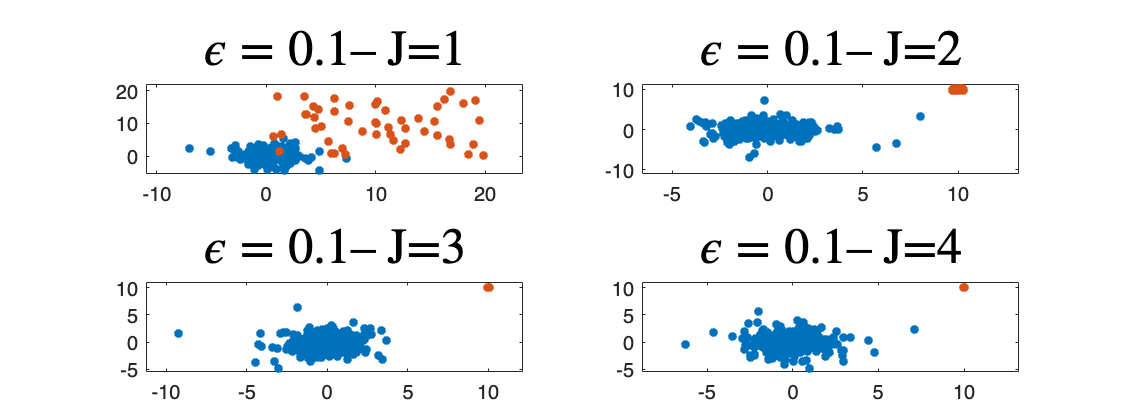

    n=500;
    p=5;
    nu=5;
    epsilon=0.1;
    C = [];
    shift = 10;
    for J=1:4
        [data, labels] = contam_t_uniform(n, p, nu, epsilon, J, shift, C);
        subplot(2,2,J);
        gscatter(data(:,1),data(:,2),labels);
        if J==0
            title('$\epsilon=0$','Interpreter','Latex','FontSize',25);
        else
            title(['$\epsilon=0.1$' '-- J=' num2str(J)],'Interpreter','Latex','FontSize',25);
        end    
        xl = xlim; yl = ylim;
        xlim(1.1*xl); ylim(1.1*yl); 
    end
    
    % make legend invisible
    lgd = findobj('type', 'legend');
    set(lgd, 'visible', 'off');

##     Scatterplots of Figure 5 of the Supplementary Information

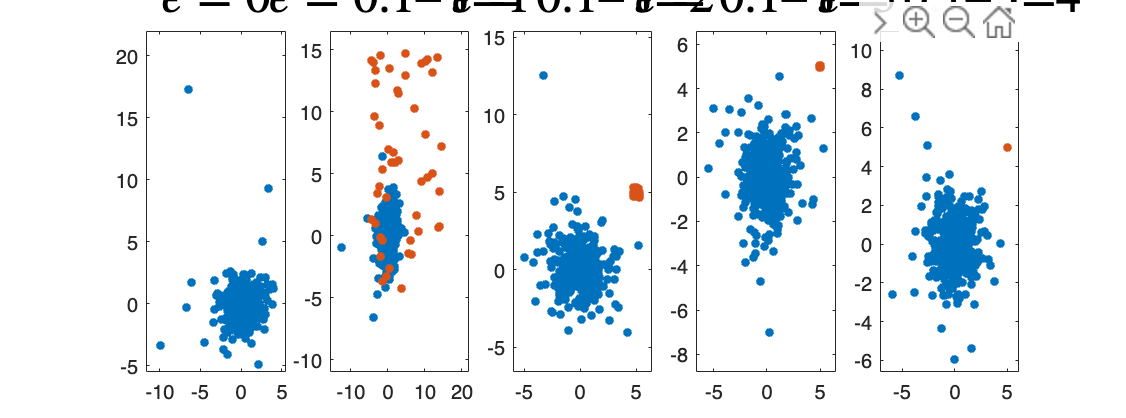

    n=500;
    p=5;
    nu=5;
    epsilon=0.1;
    C = [];
    shift = 5;
    for J=0:4
        [data, labels] = contam_t_uniform(n, p, nu, epsilon, J, shift, C);
        subplot(1,5,J+1);
        gscatter(data(:,1),data(:,2),labels);
        if J==0
            title('$\epsilon=0$','Interpreter','Latex','FontSize',25);
        else
            title(['$\epsilon=0.1$' '-- J=' num2str(J)],'Interpreter','Latex','FontSize',25);
        end    
        xl = xlim; yl = ylim;
        xlim(1.1*xl); ylim(1.1*yl); 
    end
    set(gcf,'Position',[214,338,1133,420]);
    % make legend invisible
    lgd = findobj('type', 'legend');
    set(lgd, 'visible', 'off');